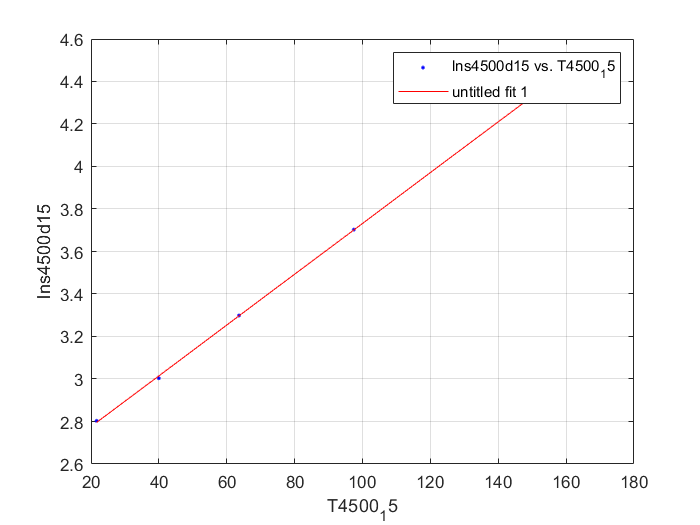

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( T4500_15, lns4500d15 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns4500d15 vs. T4500_15', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T4500_15
ylabel lns4500d15
grid on



%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01196  (0.01173, 0.01218)
  %     p2 =       2.537  (2.516, 2.557)

%Goodness of fit:
%  SSE: 0.000187
 % R-square: 0.9999
 % Adjusted R-square: 0.9999
 % RMSE: 0.007896